### Integrantes : Miguel Gutierrez y Julian Ramirez

# Punto 1

Droga administrada.

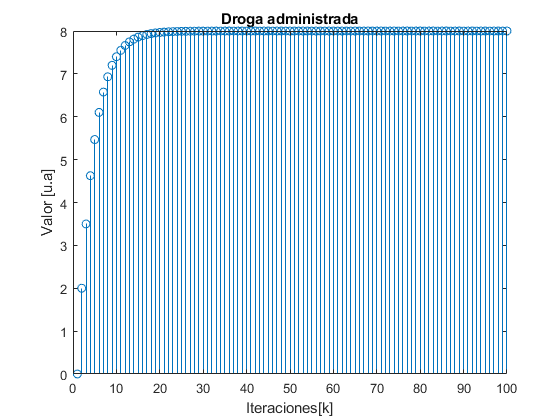

p =0.25;
b=2;
a=(1-p);
n=100;
X = zeros([1 n]);
funcion = @(X) a*X+b;
%Condicion inicial
X(1)=0;
%Simulacion
for i=2:n
    X(i)=funcion(X(i-1));
end
%Grafica
stem(X)
title('Droga administrada')
xlabel('Iteraciones[k]')
ylabel('Valor [u.a]')

Sabemos que la solución cuando $k\longrightarrow \infty$ es


$$\lim_{k\to \infty } D\left\lbrack k\right\rbrack =\left\lbrack \frac{\left(1-p\right)}{p}+1\right\rbrack D_0$$


Que con los datos que susministramos ($\left.p=0\ldotp 25,D_{0\;} =2\right)$, obtenemos que 


$$\lim_{k\to \infty } D\left\lbrack k\right\rbrack =\left\lbrack \frac{\left(0\ldotp 75\right)}{0\ldotp 25}+1\right\rbrack 2=\left\lbrack 3+1\right\rbrack 2=8$$


Al notar la grafica, parece que le hemos pegado muy bien !

# Punto 2

Amortizacion pagos iguales

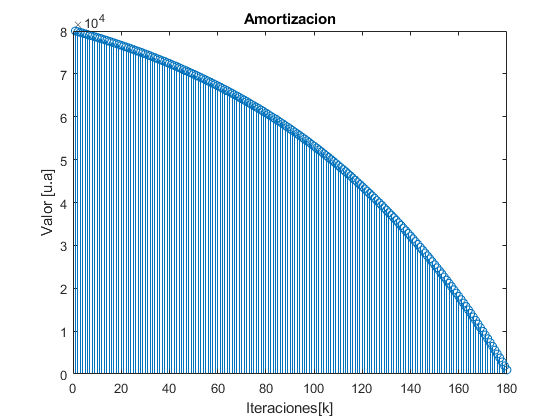

i =0.01; %Tasa de interes
b=960.1344;
a=(1+i);
n=180;
X = zeros([1 n]);
funcion = @(X) a*X-b;
%Condicion inicial
X(1)=80000;
for i=2:n
    X(i)=funcion(X(i-1));
end
stem(X)
title('Amortizacion')
xlabel('Iteraciones[k]')
ylabel('Valor [u.a]')

Sabemos como pues es mensual, entonces 15 años, sera lo mismo que 15*12 = 180 meses de pagos mensuales.

Utilizando el echo que $D\left\lbrack 180\right\rbrack =0$, podemos obtener al despejar P que:


$$P=\frac{{\left(1\ldotp 01\right)}^{180} \cdot 80\ldotp 000\;\left(-0\ldotp 01\right)}{\left(1\ldotp 01\right){-\left(1\ldotp 01\right)}^{180} -0,01}\approx 960\ldotp 1344$$


Es posible ver en la grafica que le hemos pegado ! 